# Example: COVID-2019 data for French regions

The dataset is collected from  [1]. The data quality may not be very good. There are several NaNs and incorrect data for the most recent days for the regions (24 Mars-27 Mars). 

[1] [https://github.com/cedricguadalupe/FRANCE-COVID-19](https://github.com/cedricguadalupe/FRANCE-COVID-19) 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function
% getDataCOVID_FRA
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID_FRA();
% time = time(1:end-1);
timeRef = time(1:end); % trick to avoid reloading "time" at each iteration

## Total in France

Npop= 65e6; % population
time = timeRef;

fprintf(['Most recent update: ',datestr(timeRef(end)),'\n'])

Most recent update: 28-Apr-2020


time = timeRef; % re-initialize value of time
Recovered = table2array(tableRecovered(1:end,end));
Deaths = table2array(tableDeaths(1:end,end));
Confirmed = table2array(tableConfirmed(1:end,end));

Recovered = Recovered(:)';
Deaths = Deaths(:)';
Confirmed = Confirmed(:)';
time = time(:)';

% minimal number of high-quality data required for the fitting
minNum= max(100,round(0.1*max(Confirmed)));  
% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
dummy = Confirmed - Recovered - Deaths;
Recovered(Confirmed<=minNum | isnan(dummy))=[];
Deaths(Confirmed<=minNum | isnan(dummy)) =[];
time(Confirmed<=minNum | isnan(dummy)) =  [];
Confirmed(Confirmed<=minNum | isnan(dummy)) =[];


tic

% Definition of the first estimates for the parameters
alpha_guess = 0.1; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.5; % rate at which infectious people enter in quarantine
lambda_guess = [0.1,0.1,0.1]; % recovery rate
kappa_guess = [0.1,0.05]; % death rate

guess = [alpha_guess,beta_guess,1/LT_guess, Q_guess,lambda_guess,kappa_guess];

% Initial conditions
E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
R0 = Recovered(1);
D0 = Deaths(1);


Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off','dt',1/24);

disp(lambdaFun)

    @(a,t)a(1)+exp(-a(2)*(t+a(3)))



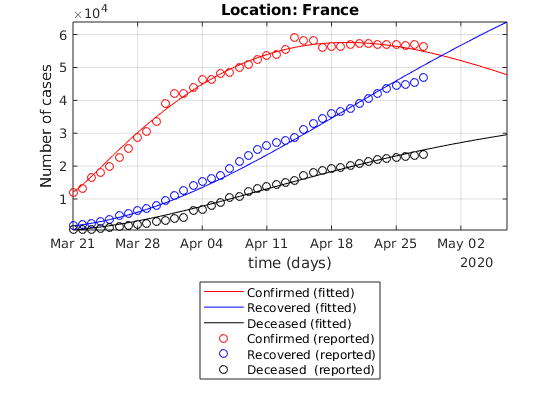


dt = 1/24; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(7)));
N = numel(time1);
t = [0:N-1].*dt;


% Call of the function SEIQRDP.m with the fitted parameters
[S,E,I,Q,R,D,P] = ...
    SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t,lambdaFun);

clf;close all;
figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Confirmed (fitted)',...
    'Recovered (fitted)','Deceased (fitted)',...
    'Confirmed (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside');
set(gcf,'color','w')
title(['Location: France'])
%%%%%%%%%%%%%

grid on
axis tight
set(gca,'yscale','lin')

toc

Elapsed time is 5.817543 seconds.


## French regions

Data after 24/03/2019 are not accounted in for the regions as they seems to be wrong.

I don't think one can trust most of the result displayed below, especially with respect to the results observed for the entire country.

clearvars;close all;clc;
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID_FRA();
minNum= 30;
minDayNum = 15; % minimal number of high-quality data required for the fitting
timeRef = time(1:end); % trick to avoid reloading "time" at each iteration
fprintf(['Most recent update: ',datestr(timeRef(end)),'\n'])

Most recent update: 28-Apr-2020


Elapsed time is 3.890666 seconds.


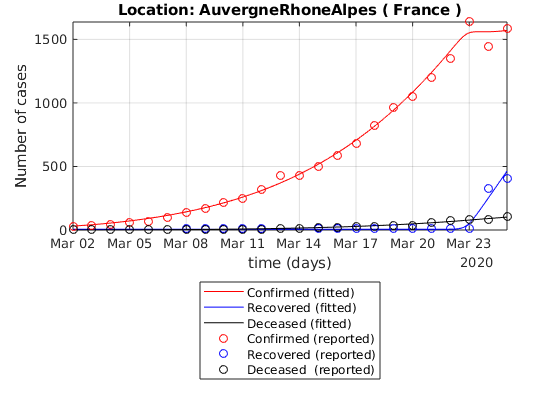

Elapsed time is 3.240576 seconds.


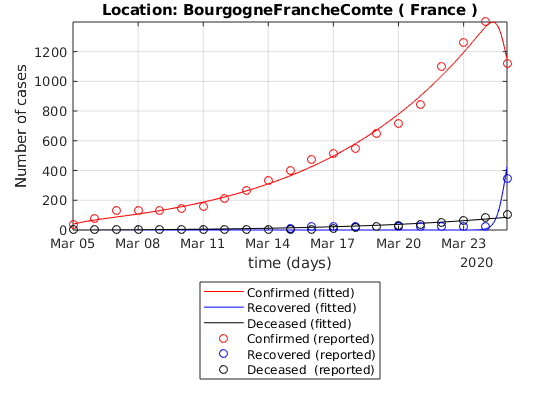

Elapsed time is 3.281563 seconds.


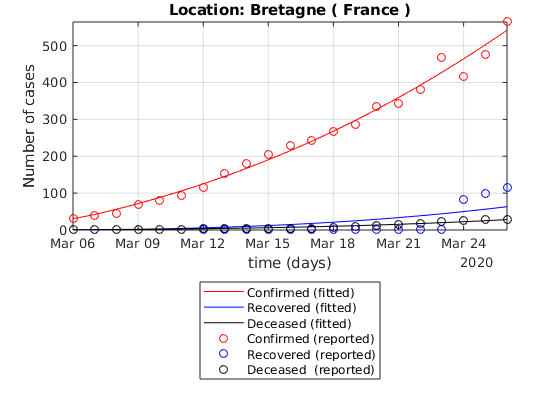

Elapsed time is 1.272620 seconds.


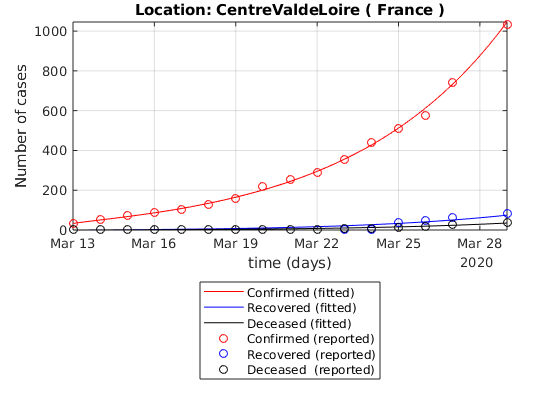

  MException with properties:

    identifier: 'optimlib:lsqncommon:ProblemNotHandled'
       message: 'The Levenberg-Marquardt algorithm does not handle bound constraints and the trust-region-reflective algorithm requires at least as many equations as variables; aborting.'
         cause: {}
         stack: [7×1 struct]
    Correction: []



Elapsed time is 2.464265 seconds.


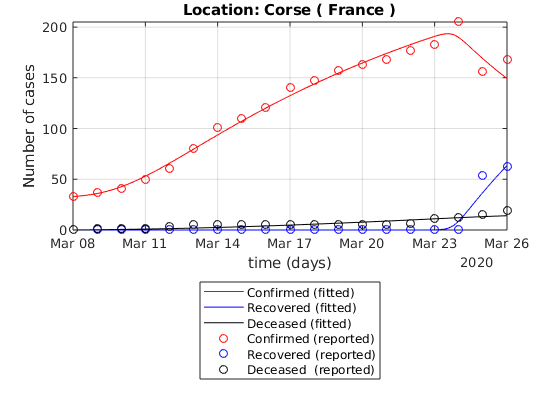

Elapsed time is 1.799545 seconds.


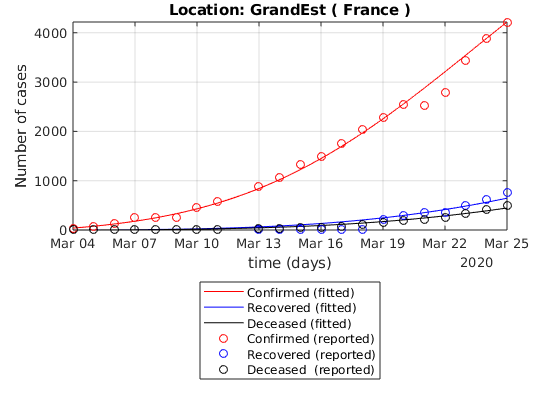

  MException with properties:

    identifier: 'optimlib:lsqncommon:ProblemNotHandled'
       message: 'The Levenberg-Marquardt algorithm does not handle bound constraints and the trust-region-reflective algorithm requires at least as many equations as variables; aborting.'
         cause: {}
         stack: [7×1 struct]
    Correction: []



Elapsed time is 3.656644 seconds.


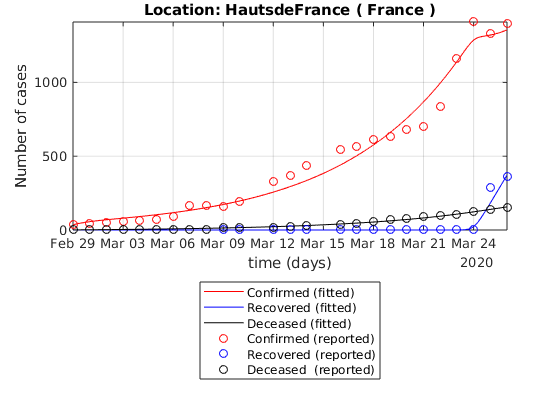

  MException with properties:

    identifier: 'optimlib:lsqncommon:ProblemNotHandled'
       message: 'The Levenberg-Marquardt algorithm does not handle bound constraints and the trust-region-reflective algorithm requires at least as many equations as variables; aborting.'
         cause: {}
         stack: [7×1 struct]
    Correction: []



Elapsed time is 3.748005 seconds.


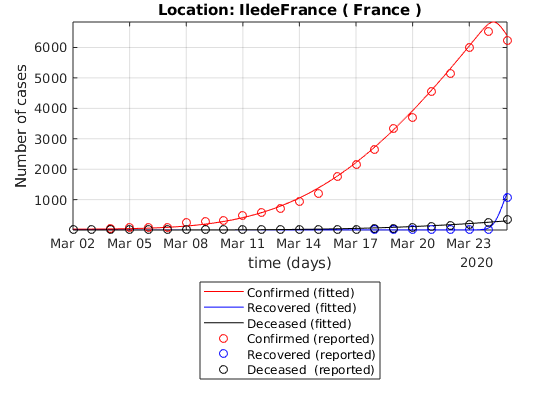

Elapsed time is 3.573688 seconds.


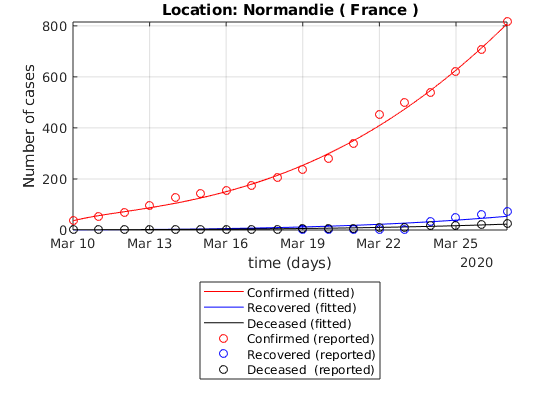

Elapsed time is 3.575146 seconds.


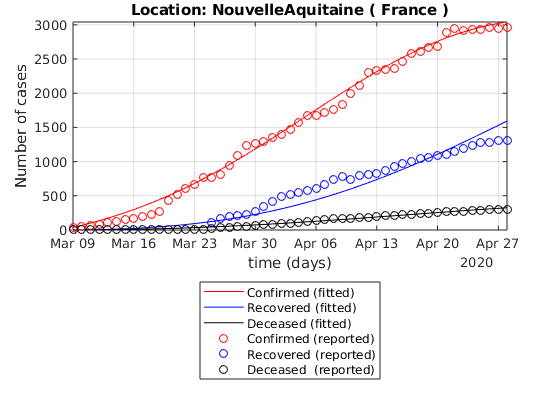

Elapsed time is 1.052252 seconds.


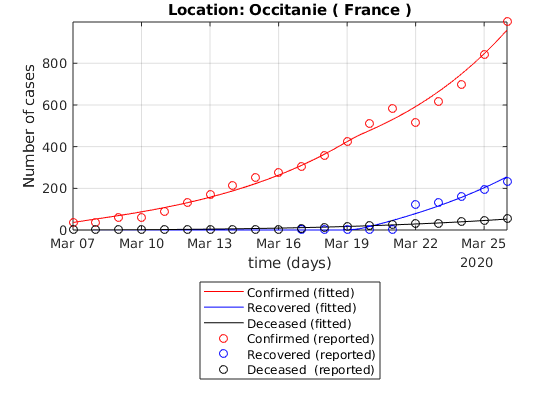

Elapsed time is 1.273174 seconds.


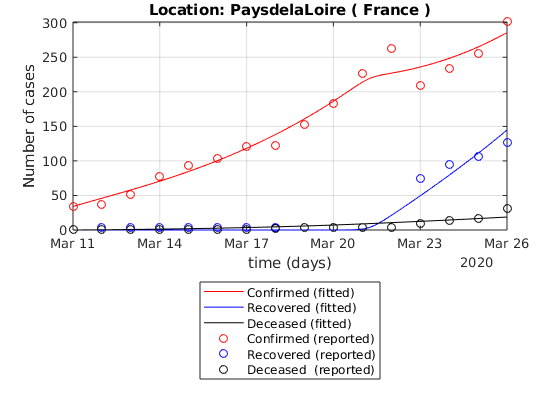

  MException with properties:

    identifier: 'optimlib:lsqncommon:ProblemNotHandled'
       message: 'The Levenberg-Marquardt algorithm does not handle bound constraints and the trust-region-reflective algorithm requires at least as many equations as variables; aborting.'
         cause: {}
         stack: [7×1 struct]
    Correction: []



Elapsed time is 1.707499 seconds.


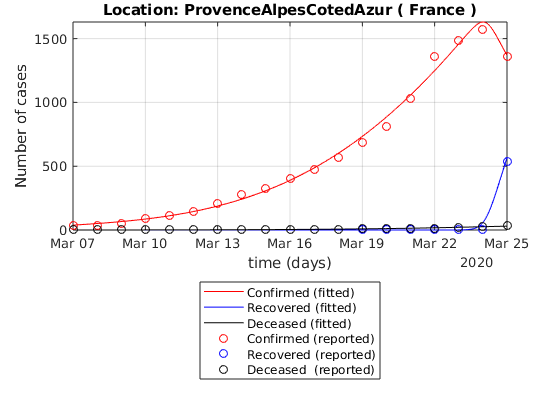


for ii = 1:size(tableConfirmed,2)-2
    
    time = timeRef; % re-initialize value of time
    Recovered = table2array(tableRecovered(1:end,ii+1));
    Deaths = table2array(tableDeaths(1:end,ii+1));
    Confirmed = table2array(tableConfirmed(1:end,ii+1));
    
    Recovered = Recovered(:)';
    Deaths = Deaths(:)';
    Confirmed = Confirmed(:)';
    time = time(:)';
    
    % If the number of confirmed Confirmed cases is small, it is difficult to know whether
    % the quarantine has been rigorously applied or not. In addition, this
    % suggests that the number of infectious is much larger than the number of
    % confirmed cases
    dummy = Confirmed - Recovered - Deaths;
    Recovered(Confirmed<=minNum | isnan(dummy))=[];
    Deaths(Confirmed<=minNum | isnan(dummy)) =[];
    time(Confirmed<=minNum | isnan(dummy)) =  [];
    Confirmed(Confirmed<=minNum | isnan(dummy)) =[];
    
    Npop= 10e6; % population (dummy number; be careful when interpreting the fitted parameters)
    % The fitting is only applied if enough data is collected
    if numel(Confirmed)>minDayNum % If more than "minDayNum" days of data, run the fit
        tic
        
        % Definition of the first estimates for the parameters
        alpha_guess = 0.06; % protection rate
        beta_guess = 1.0; % Infection rate
        LT_guess = 5; % latent time in days
        Q_guess = 0.5; % rate at which infectious people enter in quarantine
        lambda_guess = [0.1,0.1,0.1]; % recovery rate
        kappa_guess = [0.1,0.05]; % death rate
        
        guess = [alpha_guess,beta_guess,1/LT_guess, Q_guess,lambda_guess,kappa_guess];
        
        % Initial conditions
        E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
        I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
        Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
        R0 = Recovered(1);
        D0 = Deaths(1);
        
        
        Active = Confirmed-Recovered-Deaths;
        Active(Active<0) = 0; % No negative number possible
        [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun] = ...
            fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off');
        
        
        dt = 1/24; % time step
        time1 = datetime(time(1)):dt:datetime(time(end));
        N = numel(time1);
        t = [0:N-1].*dt;
        
        
        % Call of the function SEIQRDP.m with the fitted parameters
        [S,E,I,Q,R,D,P] = ...
            SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t,lambdaFun);
        
        clf;close all;
        figure
        
        semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
        hold on
        semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
        % ylim([0,1.1*Npop])
        ylabel('Number of cases')
        xlabel('time (days)')
        leg = {'Confirmed (fitted)',...
            'Recovered (fitted)','Deceased (fitted)',...
            'Confirmed (reported)','Recovered (reported)','Deceased  (reported)'};
        legend(leg{:},'location','southoutside');
        set(gcf,'color','w')
        
        %%% title %%%
        subLoc = tableRecovered.Properties.VariableNames{ii+1};
        title(['Location: ',subLoc,' ( France )'])
        %%%%%%%%%%%%%
        
        grid on
        axis tight
        set(gca,'yscale','lin')
        toc
        
        pause(1)
    end
end